# Transposition Test: Scalable online permutation test

% The transposition test performs the permutation test via the online
% computation. The code below does transposition test simulation given in
% Figure 2 of
%
% Chung, M.K., Xie, L, Huang, S.-G., Wang, Y., Yan, J., Shen, L. 2019 Rapid 
% acceleration of the permutation test via transpositions, International 
% Workshop on Connectomics in NeuroImaging, Lecture Notes in Computer Science
% 11848:42-53 
% http://www.stat.wisc.edu/~mchung/papers/chung.2019.CNI.pdf
% arXiv:1812.06696, https://arxiv.org/abs/1812.06696 
%
%
% This code is downloaded from
% http://www.stat.wisc.edu/~mchung/transpositions
%
% (C) 2019 Moo K. Chung
% University of Wisconsin-Madison
% mkchung@wisc.edu
%
% Update history: created : 2019 July 27; 2019 August 20; 2020 April 20 
%
%---------------------------
%% Load simulation example (Figure 1) in Chung et al. (2019)

load 'simulation-10-10.mat' 

%The following 20 simulated data was stored
% [store_x store_y]
% 
%     0.1518   -0.5024
%    -2.2439   -0.0720
%     1.3997   -0.2961
%    -0.0870    2.6186
%     1.3410   -1.0642
%    -0.0827    0.6154
%    -0.6020   -1.0312
%    -0.3239   -0.3594
%     0.3427    0.5049
%     0.3127   -0.4557
%
% These numbers were generated from the model
% x = 0.1 + normrnd(0,1,m,1);
% y = normrnd(0,1,n,1);
% store_x =x; store_y = y;

%Sample size in each group
m=size(store_x,1); %m=10
n=size(store_y,1); %n=10

%If you want to use the vector data (whole images/brain), variable store_x
%has to be size m x l, where l is the number of voxels, nodes or
%measurements. Similarly variable store_y has to be size n x l. 


%Number of permutations/transpositions
per_s=100000; %Number of permutations in the standard permutation test. 
per_t=8000000; %Number of transpostions in the transposition test. 

%How many algebraic operations standard methods will be using with respect to the
%transposition test?
%ratio=(4*(m+n)+20)/35; 
%Theoretically,the transpostion test generates 2.85 times more
%permutations for the small sample study. However, as the sample size
%increases, we are generating far more permutations. When m=n=200, we are
%generating 46 times more permutations. However, computationlly, the
%transposition test generates far more than the theoretical estimate since the
%method uses far less compuational resources including memory. Thus, you
%may want to set this 
%per_t = round(per_s*ratio)*alpha, where alpha is somewhere between 10-100
%and depends on your hardware. Then both method's run time will be identical. 
%However, in this simulation we set per_t = per_s *80.

x=store_x; y=store_y;
observed=(mean(x)-mean(y))*sqrt(m*n*(m+n-2)/((m+n)*((m-1)*var(x)+(n-1)*var(y)))) %ground truth t-stat value: 

observed = 0.0533

p_truth = 1- tcdf(abs(observed),m+n-2)  %ground truth p-value

p_truth = 0.4790

%observed = 0.0533
%p_truth = 0.4790    
%[h, p, ci, stat] =ttest2(x,y) gives the same exact ground truth based on the two
%sided test based on the built-in MATLAB function. 

## Standard Permutaiton test

%computes the t-statistic for each permutation and save it to stat_s.
%time_s is the run time of the standard permutation test
x=store_x; y=store_y;
[stat_s, time_s] = test_permute(x,y,per_s); 

Elapsed time is 0.186928 seconds.


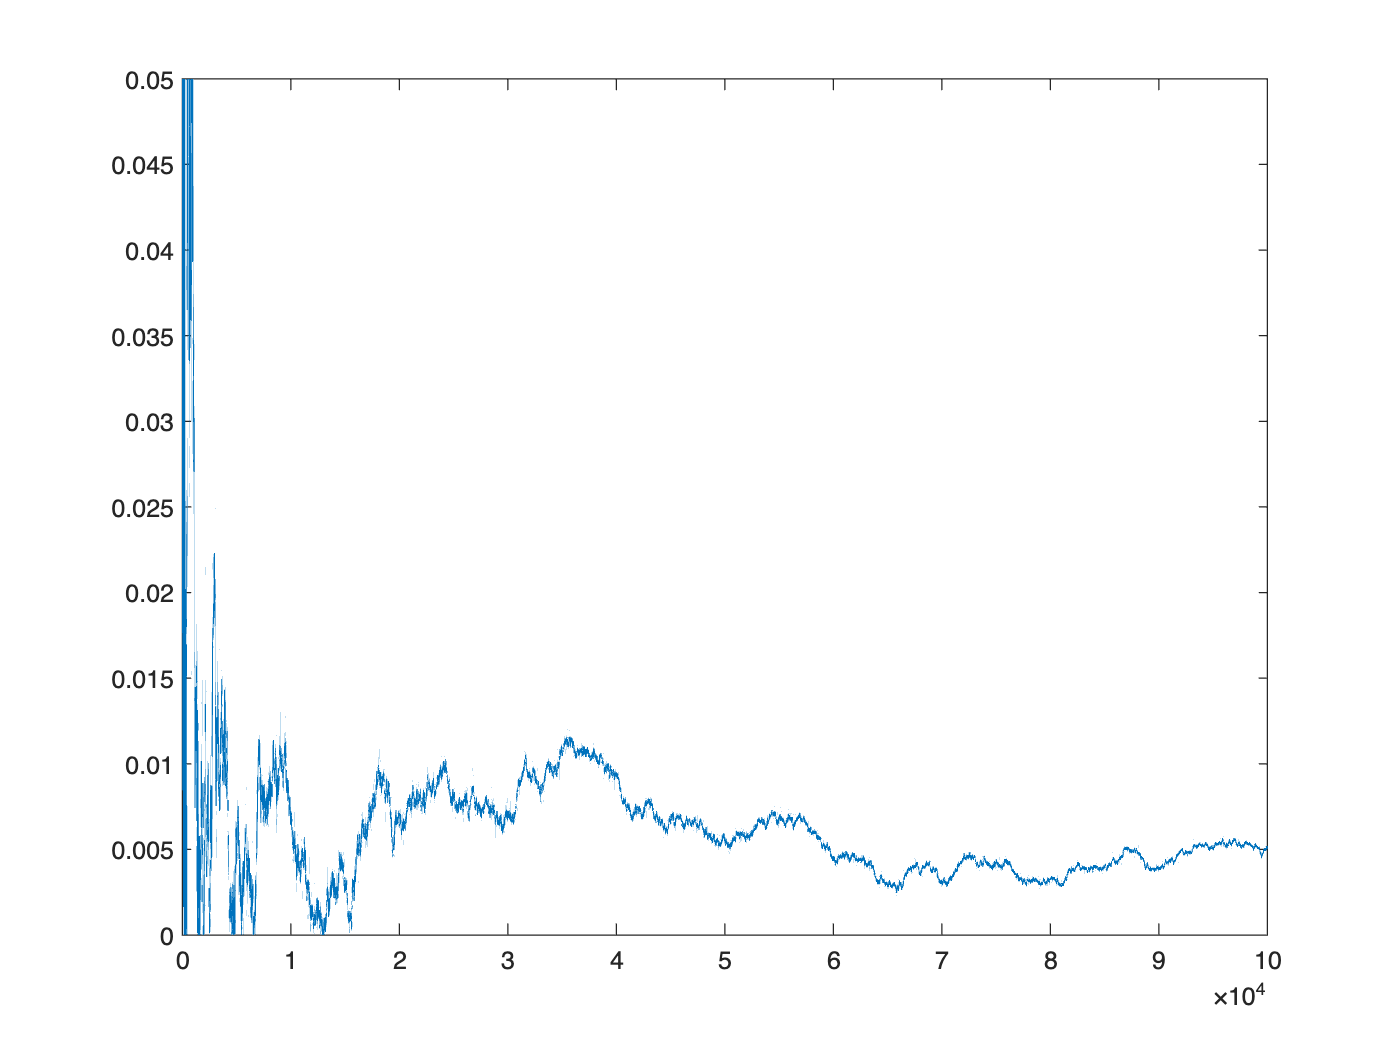

%Elapsed time is 0.968684 seconds.
 
%P-values are computed iteratively over the number
%of permutatations. See Chung et al. (20019) for detail.
%The flucatation of p-value over the number of permutation will show if
%algorithm is converging or not.
pvalue_s = online_pvalue(stat_s, observed);

%The relative error of how pvalue converges to the ground truth
rate_s = abs(pvalue_s-p_truth)/p_truth;
figure; plot(rate_s); ylim([0 0.05])

## Transposition test

%computes the t-statistic for each transposition and save it to stat_t.
%time_t is the run time of the transposition test
x=store_x; y=store_y;
[stat_t, time_t] = test_transpose(x,y,per_t); 

Elapsed time is 0.104685 seconds.


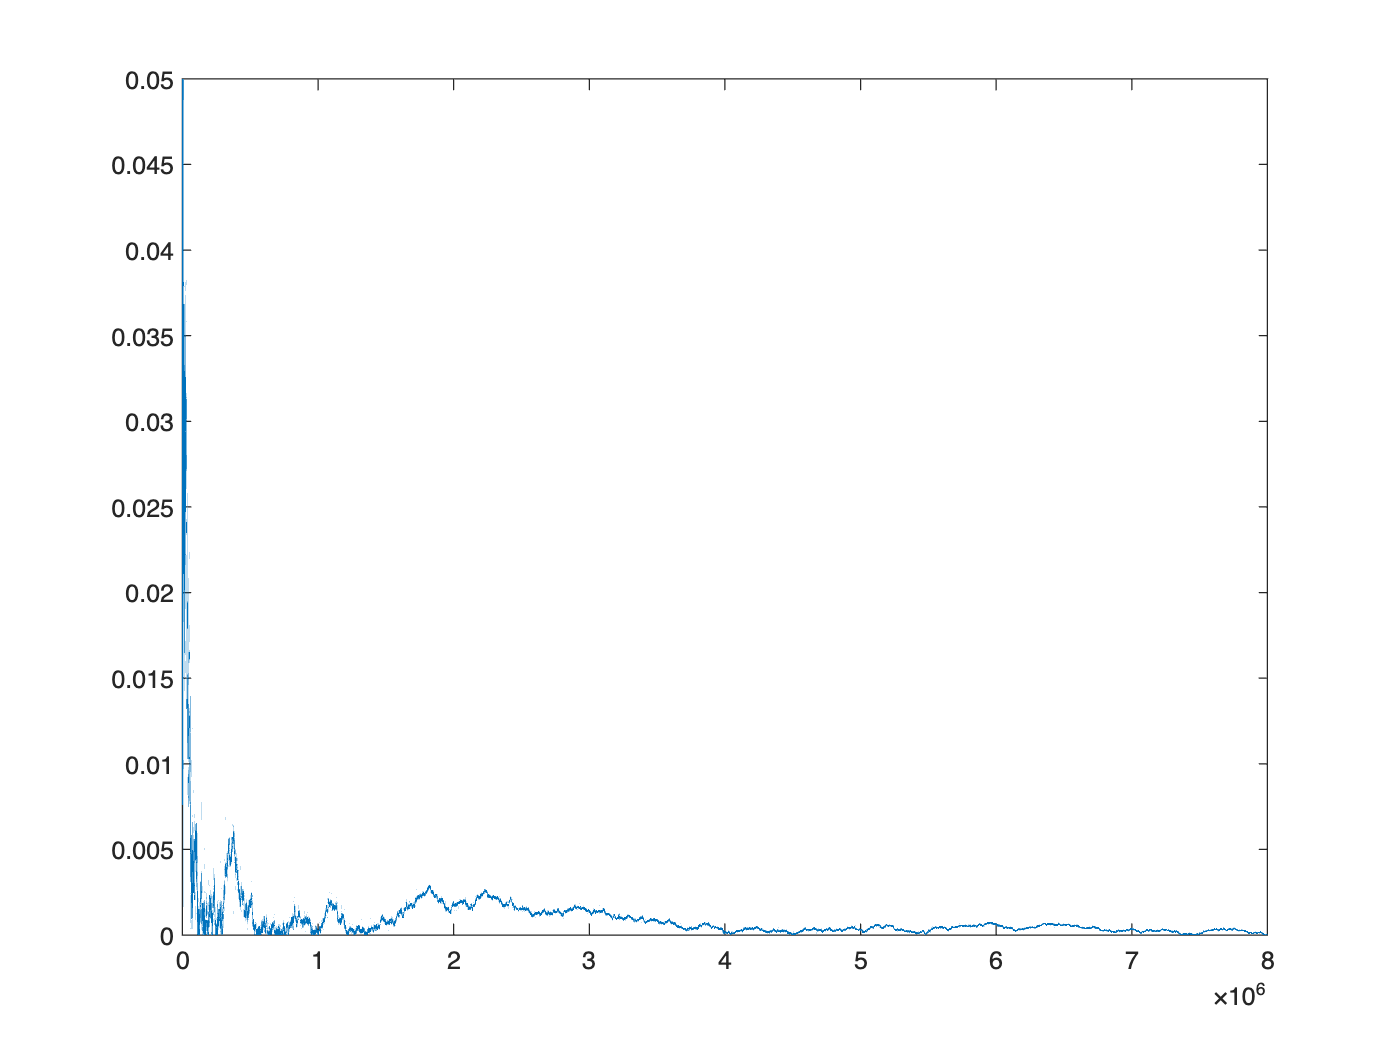

%Elapsed time is 0.916498 seconds.

%P-values are computed iteratively over the number
%of permutatations. See Chung et al. (20019) for detail.
%The flucatation of p-value over the number of permutation will show if
%algorithm is converging or not.
pvalue_t = online_pvalue(stat_t, observed);

%The relative error of how pvalue converges to the ground truth
rate_t = abs(pvalue_t-p_truth)/p_truth;
figure; plot(rate_t); ylim([0 0.05]); 

## Perfomrance comparisons

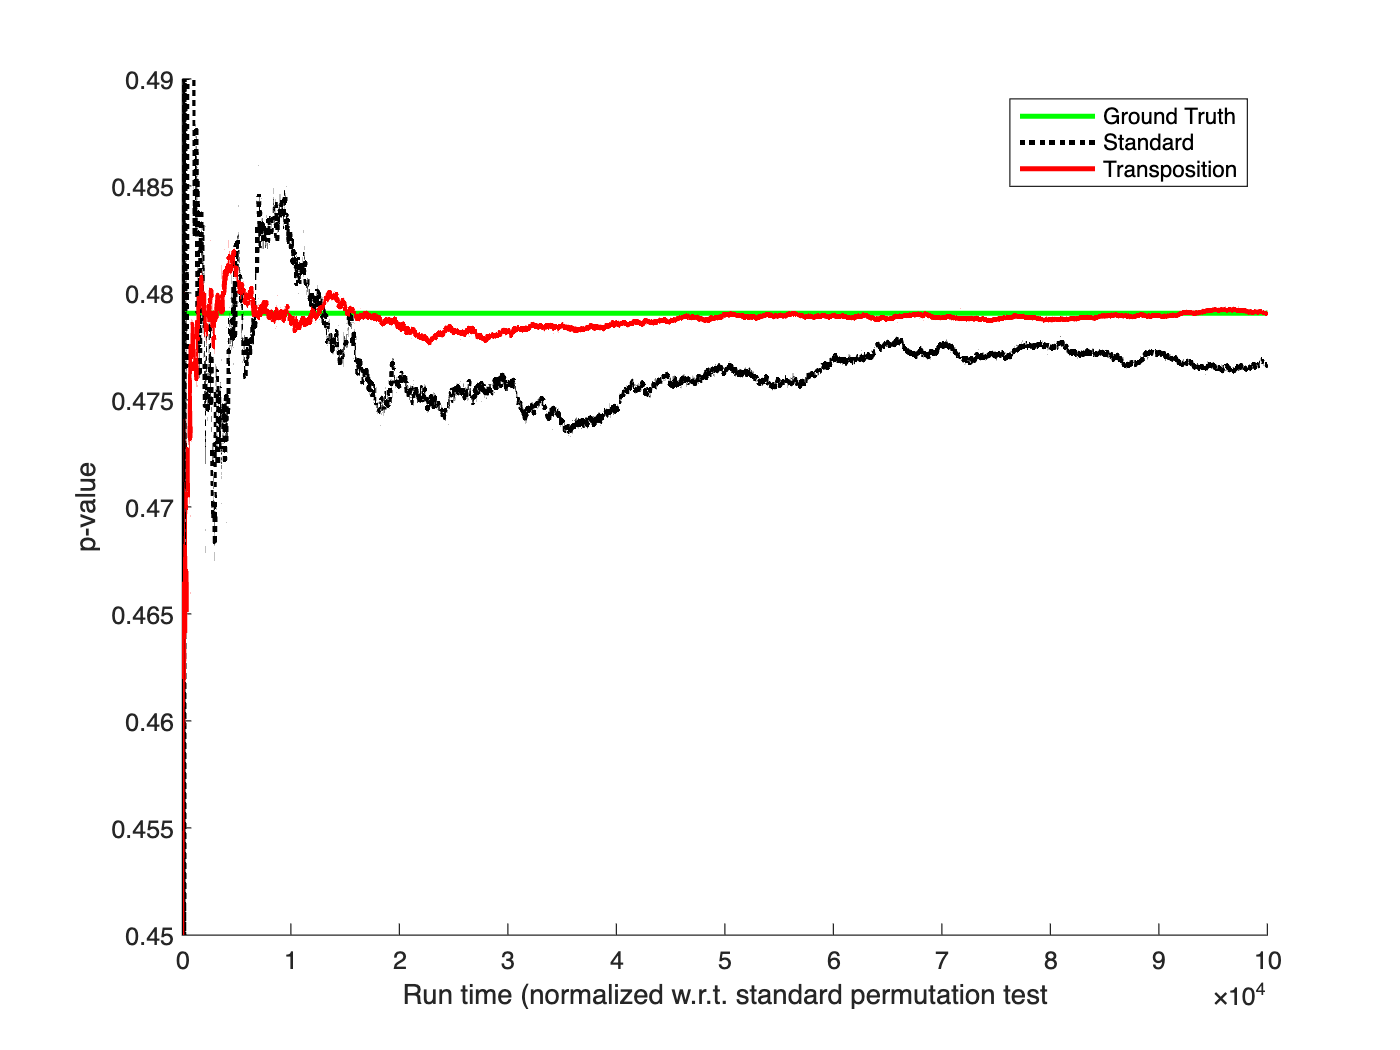

% In the cited paper, the reported results are averaged over 100 independent
% simulations. Here we show only a single simulation example.
% There are many possible ways to intermix full permutations and successive
% transpositions to improve computational performance. A systematic study of
% optimal mixing strategies is left as an exercise and remains
% an open implementation issue (potential Research Project).


%Displays the convergence of p-value to the ground truth (Figure 2-a).
figure; 
hold on; plot([0 per_s], [p_truth, p_truth], '-g', 'LineWidth',2)
hold on; plot(pvalue_s, ':k', 'LineWidth',2);  %standard method
hold on; plot(pvalue_t(1:80:per_t), '-r', 'LineWidth',2) %rapid one seed
legend('Ground Truth', 'Standard', 'Transposition')
ylim([0.45 0.49]);
xlabel('Run time (normalized w.r.t. standard permutation test'); ylabel('p-value')

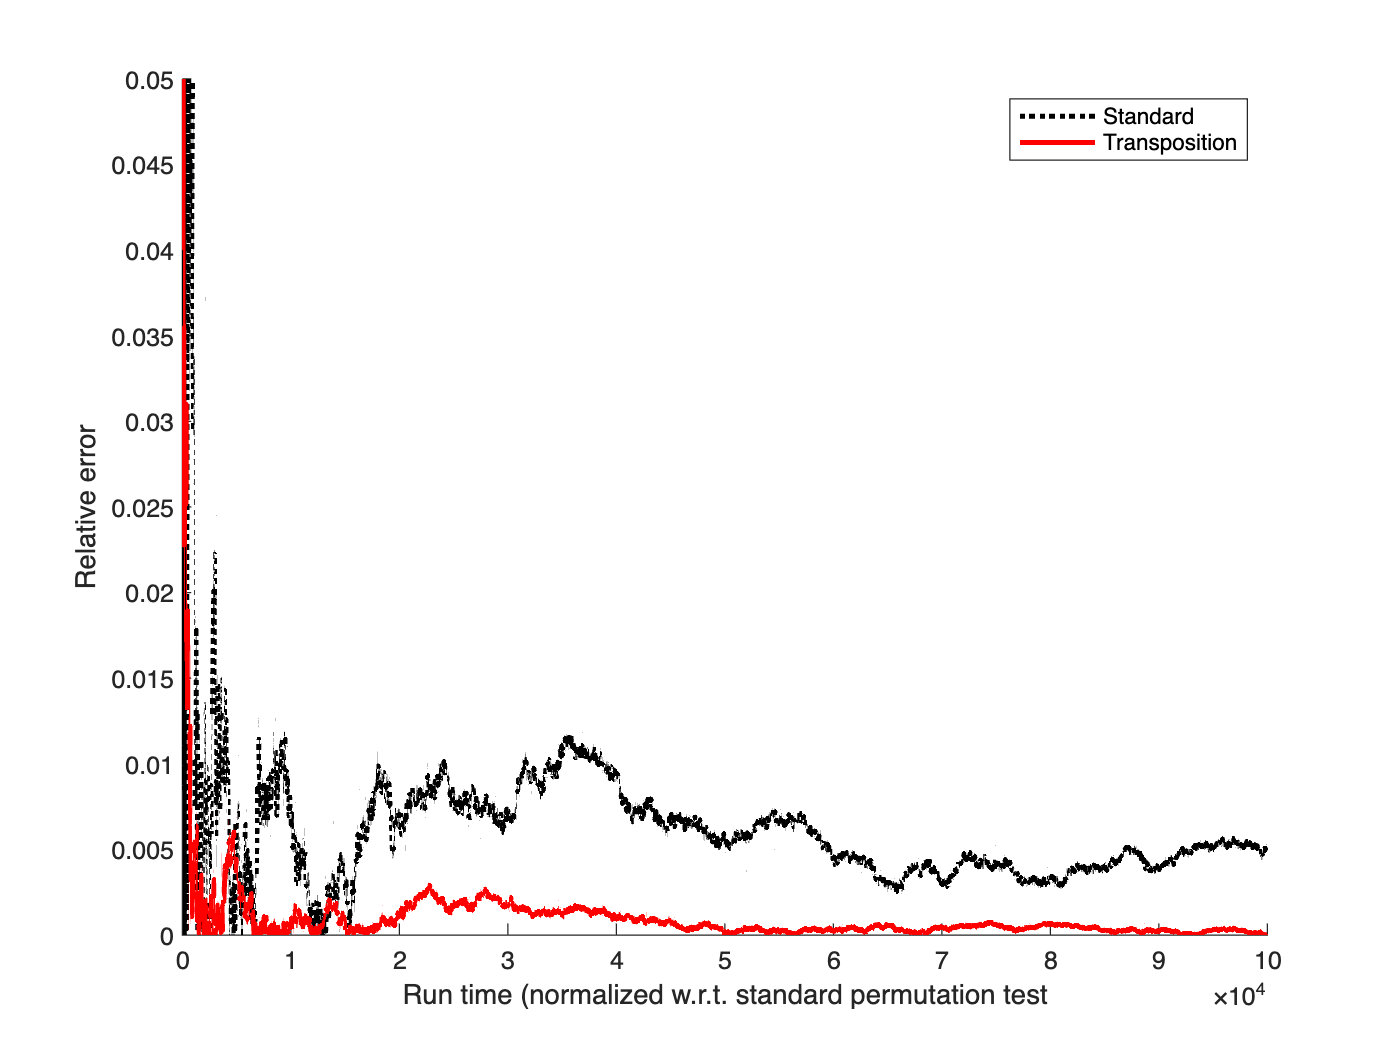

%rate of convergence
figure
hold on; plot(rate_s, ':k', 'LineWidth',2);  %standard permutation
hold on; plot(rate_t(1:80:per_t), '-r', 'LineWidth',2) %transposition
ylim([0 0.05]); 
legend('Standard', 'Transposition')
xlabel('Run time (normalized w.r.t. standard permutation test'); ylabel('Relative error')

## Accelerating the convergence of the transposition test

%Accelerate the convergence and avoids the posible bias by interjecting 
%the random permutation test within the transposition test. That can be 
%easily achieved by running iterations.For detail, read Chung et al. (2019).

stat_t=[]; per_t=5000;
for i=1:100
    [stat, time] = test_transpose(x,y,per_t/100);
    stat_t=[stat_t; stat];
    time_t=time_t+time;
end

Elapsed time is 0.003295 seconds.
Elapsed time is 0.001273 seconds.
Elapsed time is 0.003043 seconds.
Elapsed time is 0.000299 seconds.
Elapsed time is 0.000115 seconds.
Elapsed time is 0.000095 seconds.
Elapsed time is 0.000080 seconds.
Elapsed time is 0.000076 seconds.
Elapsed time is 0.000695 seconds.
Elapsed time is 0.000074 seconds.
Elapsed time is 0.000086 seconds.
Elapsed time is 0.000067 seconds.
Elapsed time is 0.000069 seconds.
Elapsed time is 0.000053 seconds.
Elapsed time is 0.000054 seconds.
Elapsed time is 0.000193 seconds.
Elapsed time is 0.000131 seconds.
Elapsed time is 0.000109 seconds.
Elapsed time is 0.000151 seconds.
Elapsed time is 0.000053 seconds.
Elapsed time is 0.000052 seconds.
Elapsed time is 0.000052 seconds.
Elapsed time is 0.000061 seconds.
Elapsed time is 0.000072 seconds.
Elapsed time is 0.000062 seconds.
Elapsed time is 0.000062 seconds.
Elapsed time is 0.000081 seconds.
Elapsed time is 0.000063 seconds.
Elapsed time is 0.000066 seconds.
Elapsed time i

%In this example, we are interjecting one permutation in every 5000
%transpositions. Repeately doing this 100 times, we achive 0.5 million
% transpositons. 


%---------------------------------------------
%% Transpositon test on whole brain or network

% The functions accept vector data. If you vecotrize your data, you can
% easily perform the transpostion test. 
%
% Suppose we generated the following simulated vecor data, 
% where group 1 has m=10 subjects and group 2 has n=12 subjects over l=1000
% voxels.

m=10; n=12; l=1000; per_t=100000;

x= normrnd(0,1,m,l);   %x is matrix of size 10 x 1000
y= normrnd(0.1,1,n,l); %y is matrix of size 10 x 1000

%Then the transposition test is done as
[stat_t, time_t] = test_transpose(x,y,per_t); 

Elapsed time is 0.161689 seconds.


%Elapsed time is 2.806940 seconds.

%The p-value is then computed as
observed=(mean(x)-mean(y)).*sqrt(m*n*(m+n-2)./((m+n)*((m-1)*var(x)+(n-1)*var(y)))); %ground truth t-stat value: 

observed =     1.7088    0.5021   -1.0644    0.5524    1.3049   -0.7531   -1.2645    0.1284    0.0460   -1.5006   -0.0934   -0.0446    0.0560   -0.4513   -2.4873    0.1120   -0.5856    1.0271    0.1856   -1.1845    0.6874   -1.0790   -0.8391   -3.1983   -1.7142    2.3603    0.0849   -0.2075    0.3560   -0.9955   -0.2280    0.8170   -0.1906    2.3613    1.4339   -0.6981   -0.8605   -0.1704    1.1576    0.1975    1.1595    1.3761    0.0243    0.3161   -0.4645    1.7771   -0.2439   -0.8973   -0.9401    1.0861


pvalue_t = online_pvalue(stat_t, observed);

